# ELE 888/ EE 8209: Lab 2: Multilayer Neural Network

### By: Jamal Abdi (500770871), Robert Coleman (500740986), Niharika Shetty (500754054)

Part 1 Variable Set Up and Declaration

x1 = [-1 -1 1 1];
x2 = [-1 1 -1 1];
t = [-1 1 1 -1];
eta = 0.1;
theta = 0.001;
b = 1;
a = 0.1;
w_in_hidden = (b-a).*rand(2,2) + a;
bias_hidden = (b-a).*rand(1,2) + a;
w_hidden_output = (b-a).*rand(2,1) + a;
bias_output = (b-a).*rand(1,1) + a;
accuracy = [];

In this section here we construct the 2-2-1 neural network with batch backpropogation, solving for the classical XOR problem. 

for r = 1:200
    delta_in_hidden = zeros(size(w_in_hidden, 1), size(w_in_hidden,2));
    delta_hidden_output = zeros(size(w_hidden_output, 1), size(w_hidden_output,2));
    delta_bias_output = zeros(size(bias_output, 1),size(bias_output, 2));
    delta_bias_hidden = zeros(size(bias_hidden, 1),size(bias_hidden, 2));
    for m = 1:size(x1, 2)
        input = [x1(m) x2(m)];
        [ y, net_j, z, net_k ] = run_network(w_in_hidden, bias_hidden, w_hidden_output, bias_output, input);
    
        fnet_k = 1 - tanh(net_k).^2;
        delta_k = (t(m)-z)*fnet_k; 
        delta_hidden_output = delta_hidden_output + ((eta*delta_k).*y)';
        delta_bias_output = delta_bias_output + (eta*delta_k*bias_output);
        
        fnet_j = (1-tanh(net_j).^2);
        delta_j = fnet_j*sum(w_hidden_output*delta_k);
        delta_in_hidden = delta_in_hidden + sum((eta*delta_j).*input);
        delta_bias_hidden = delta_bias_hidden + (eta*delta_j).*bias_hidden;
    end
    
    w_in_hidden = w_in_hidden + delta_in_hidden;
    w_hidden_output = w_hidden_output + delta_hidden_output;
    bias_output = bias_output + delta_bias_output;
    bias_hidden = bias_hidden + delta_bias_hidden;
    
    answers = zeros(size(m, 1), size(m, 2));
    
    for m = 1:size(x1, 2)
        input = [x1(m) x2(m)];
        [ ~, ~, z, ~ ] = run_network(w_in_hidden, bias_hidden, w_hidden_output, bias_output, input);
        answers(m) = z;
    end
    
    weight = 1/2*(sum((t-answers).^2));
    accuracy = [accuracy weight];
    
    if weight < theta
        break;
    end
end

Here we verify the computed final weight vectors satify the XOR operation. The learning curve and number of epochs are graphed.

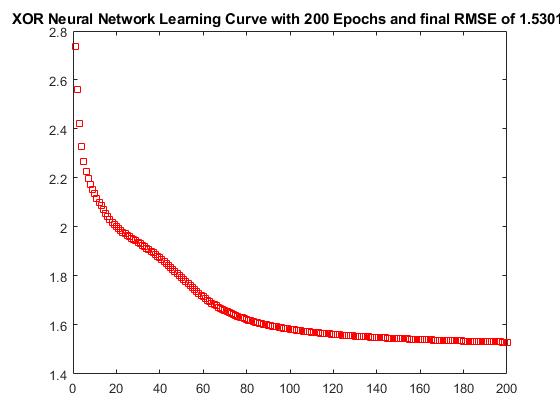

for m = 1:4
    input = [x1(m) x2(m)];
    [ ~, ~, z, ~ ] = run_network(w_in_hidden, bias_hidden, w_hidden_output, bias_output, input);
    answers(m) = z;
end
    
weight = 1/2*(sum((t-answers).^2));
figure
plot(1:size(accuracy,2), accuracy,'rs'); title(['XOR Neural Network Learning Curve with ', num2str(r), ' Epochs and final RMSE of ', num2str(weight), '.']);

Part 2 Variable Set Up and Declaration

load wine.data

class_1 = wine(find(wine(:, 1) == 1), 1:3);
class_3 = wine(find(wine(:, 1) == 3), 1:3);
class_3(:, 1) = -1;
x1 = [class_1(:, 2)' class_3(:, 2)'];
x2 = [class_1(:, 3)' class_3(:, 3)'];
t = [class_1(:, 1)' class_3(:, 1)'];
eta = 0.1;
theta = 0.001;
b = 1;
a = 0.1;
w_in_hidden = (b-a).*rand(2,2) + a;
bias_hidden = (b-a).*rand(1,2) + a;
w_hidden_output = (b-a).*rand(2,1) + a;
bias_output = (b-a).*rand(1,1) + a;
accuracy = [];

Here we repeat the above for the Wine data set using Classes 1 and 3 and features x1 and x2.

for r = 1:200
    delta_in_hidden = zeros(size(w_in_hidden, 1), size(w_in_hidden,2));
    delta_hidden_output = zeros(size(w_hidden_output, 1), size(w_hidden_output,2));
    delta_bias_output = zeros(size(bias_output, 1),size(bias_output, 2));
    delta_bias_hidden = zeros(size(bias_hidden, 1),size(bias_hidden, 2));
    for m = 1:size(x1, 2)
        input = [x1(m) x2(m)];
        [ y, net_j, z, net_k ] = run_network(w_in_hidden, bias_hidden, w_hidden_output, bias_output, input);
    
        fnet_k = 1 - tanh(net_k).^2;
        delta_k = (t(m)-z)*fnet_k; 
        delta_hidden_output = delta_hidden_output + ((eta*delta_k).*y)';
        delta_bias_output = delta_bias_output + (eta*delta_k*bias_output);
        
        fnet_j = (1-tanh(net_j).^2);
        delta_j = fnet_j*sum(w_hidden_output*delta_k);
        delta_in_hidden = delta_in_hidden + sum((eta*delta_j).*input);
        delta_bias_hidden = delta_bias_hidden + (eta*delta_j).*bias_hidden;
    end
    
    w_in_hidden = w_in_hidden + delta_in_hidden;
    w_hidden_output = w_hidden_output + delta_hidden_output;
    bias_output = bias_output + delta_bias_output;
    bias_hidden = bias_hidden + delta_bias_hidden;
    
    answers = zeros(size(m, 1), size(m, 2));
    
    for m = 1:size(x1, 2)
        input = [x1(m) x2(m)];
        [ ~, ~, z, ~ ] = run_network(w_in_hidden, bias_hidden, w_hidden_output, bias_output, input);
        answers(m) = z;
    end
    
    weight = 1/2*(sum((t-answers).^2));
    accuracy = [accuracy weight];
    
    if weight < theta
        break;
    end
end

Here we calculate the Wine classification accuracy with the computed final weight vectors. The learning curve and number of epochs are graphed.

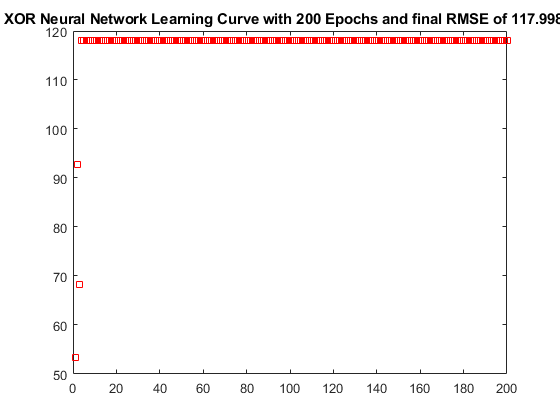

for m = 1:size(x1, 2)
    input = [x1(m) x2(m)];
    [ ~, ~, z, ~ ] = run_network(w_in_hidden, bias_hidden, w_hidden_output, bias_output, input);
    answers(m) = z;
end
    
weight = 1/2*(sum((t-answers).^2));
figure
plot(1:size(accuracy,2), accuracy,'rs'); title(['XOR Neural Network Learning Curve with ', num2str(r), ' Epochs and final RMSE of ', num2str(weight), '.']);

function [ y, net_j, z, net_k ] = run_network(weight_ji, bias_j, weight_kj, bias_k, inputs)
    % Let input be a column vector of inputs
    % Let wight_ji by a matrix where every row is the weight associated with
    % its input
    % Let weight_kj by a matrix where every row is the weight associated
    % with its input
    net_j = (inputs*weight_ji) + bias_j;
    y = tanh(net_j);
    net_k = (y*weight_kj) + bias_k;
    z = tanh(net_k);
end